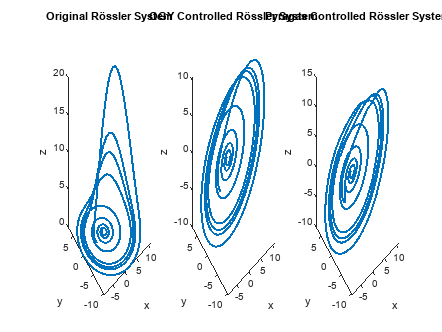

clc; 
close all;
clear; 


% Rössler system parameters
a = 0.2;
b = 0.2;
c = 5.7;

% OGY method control parameters
eta = 0.1;
eps = 0.1;
gamma = 1;

% Pyragas method control parameters
tau = 1;
epsilon = 0.1;

% Rössler system equations
dxdt = @(t,x) [-x(2)-x(3); x(1)+a*x(2); b + x(3)*(x(1)-c)];

% Initial conditions
x0 = [0; 0.5; 0];

% Time interval
tspan = [0 50];

% Solve the ODE using MATLAB's ode45 solver
[t,x] = ode45(dxdt, tspan, x0);

% Calculate the OGY control signal
y_ogy = x(:,1) + eta*(x(:,3) - x(:,1));
y_ogy(1) = y_ogy(2); % remove first control signal value to match x and y sizes

% Calculate the Pyragas control signal
N = length(x);
y_pyragas = zeros(N,1);
for i = 1:N
    y_pyragas(i) = x(mod(i+round(tau/diff(tspan)),N)+1,1) + epsilon*(x(i,3) - x(mod(i+round(tau/diff(tspan)),N)+1,3));
end

% Plot the original Rössler system and the controlled systems
figure;
subplot(1,3,1);
plot3(x(:,1), x(:,2), x(:,3), 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
zlabel('z');
title('Original Rössler System');

subplot(1,3,2);
plot3(x(:,1), x(:,2), y_ogy, 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
zlabel('z');
title('OGY Controlled Rössler System');

subplot(1,3,3);
plot3(x(:,1), x(:,2), y_pyragas, 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
zlabel('z');
title('Pyragas Controlled Rössler System');